# Perform HIL Testing

For this example, we are going to use TI Microcontroller Developement Kit (see image below) as a production controller and Speedgoat Baseline target machine as plant simulator. 

- We need to deploy our [controller logic](matlab:open_system('focVelocityEncoder_F28069');) for PMSM onto TI microcontroller using Embedded Coder.   

- We deploy our plant model with rest of the test harness onto Baseline target machine. We will instrument our [plant model](matlab:open_system('PMSM_hilModel');) to read PWMs and Inverter Enable commands from TI Microcontroller using PMW Capture blocks from Speedgoat I/O Blockset and update motor speed and phase currents via QAE - Quadrature Encoder and Analog Output driver blocks. 

- Next, connect TI microcontroller board to Baseline target machine.

- To perform closed-loop testing in real-time, we will deploy our plant model onto Baseline target machine and execute it in real-time.

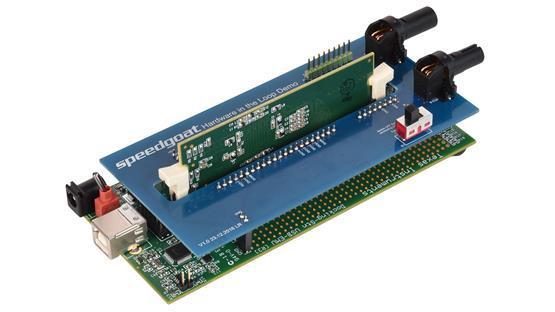

## **Deploy Controller Model on TI F2806x ISO controlCARD ** (requires Motor Control Blockset)

`NOTES:` `Ensure TI controlCard is connected to Host-Machine via USB Cable`

`Ensure `Embedded Coder Support Package for Texas Instruments C2000 Processors is installed

You must have a license for Motor Control Blockset in order to deploy application to TI Controller

See Production.mlx

mdl = 'focVelocityEncoder_F28069';
open_system(mdl);
% Build and Deploy Code to TI Controller
rtwbuild(mdl);

## **Run HIL Test on Speedgoat Real-Time Target Machine**

`NOTE:` `Due to 20kHz Sampling Rate, Graphics Mode in SLRT Kermel must be disabled.`

tg = slrt
mdl = 'FieldOrientedController_HIL';
proj = matlab.project.rootProject
cd(proj.SimulinkCodeGenFolder) %move to build folder
open_system(mdl);
rtwbuild(mdl);
tg = slrealtime;
load(tg,mdl);
tg=slrt;
tg.start;
tg.setStopTime(5);
while strcmp(tg.Status,'running')
    % wait
    pause(1);
end
Simulink.sdi.view;

**Restore Data Dictionary**


clear mdl adc adcStruct ddddPlant ddCntrl